## Interactive plot -- look at kernels for each point

### Weibull

clear
load('C:\Users\eschlatter\Dropbox\DispersalEvolution\cost_ben_model\nmax_0\weibull_MK.mat')
load('C:\Users\eschlatter\Dropbox\DispersalEvolution\cost_ben_model\weibull_params.mat')
mk = [out_mortcost out_kincost];

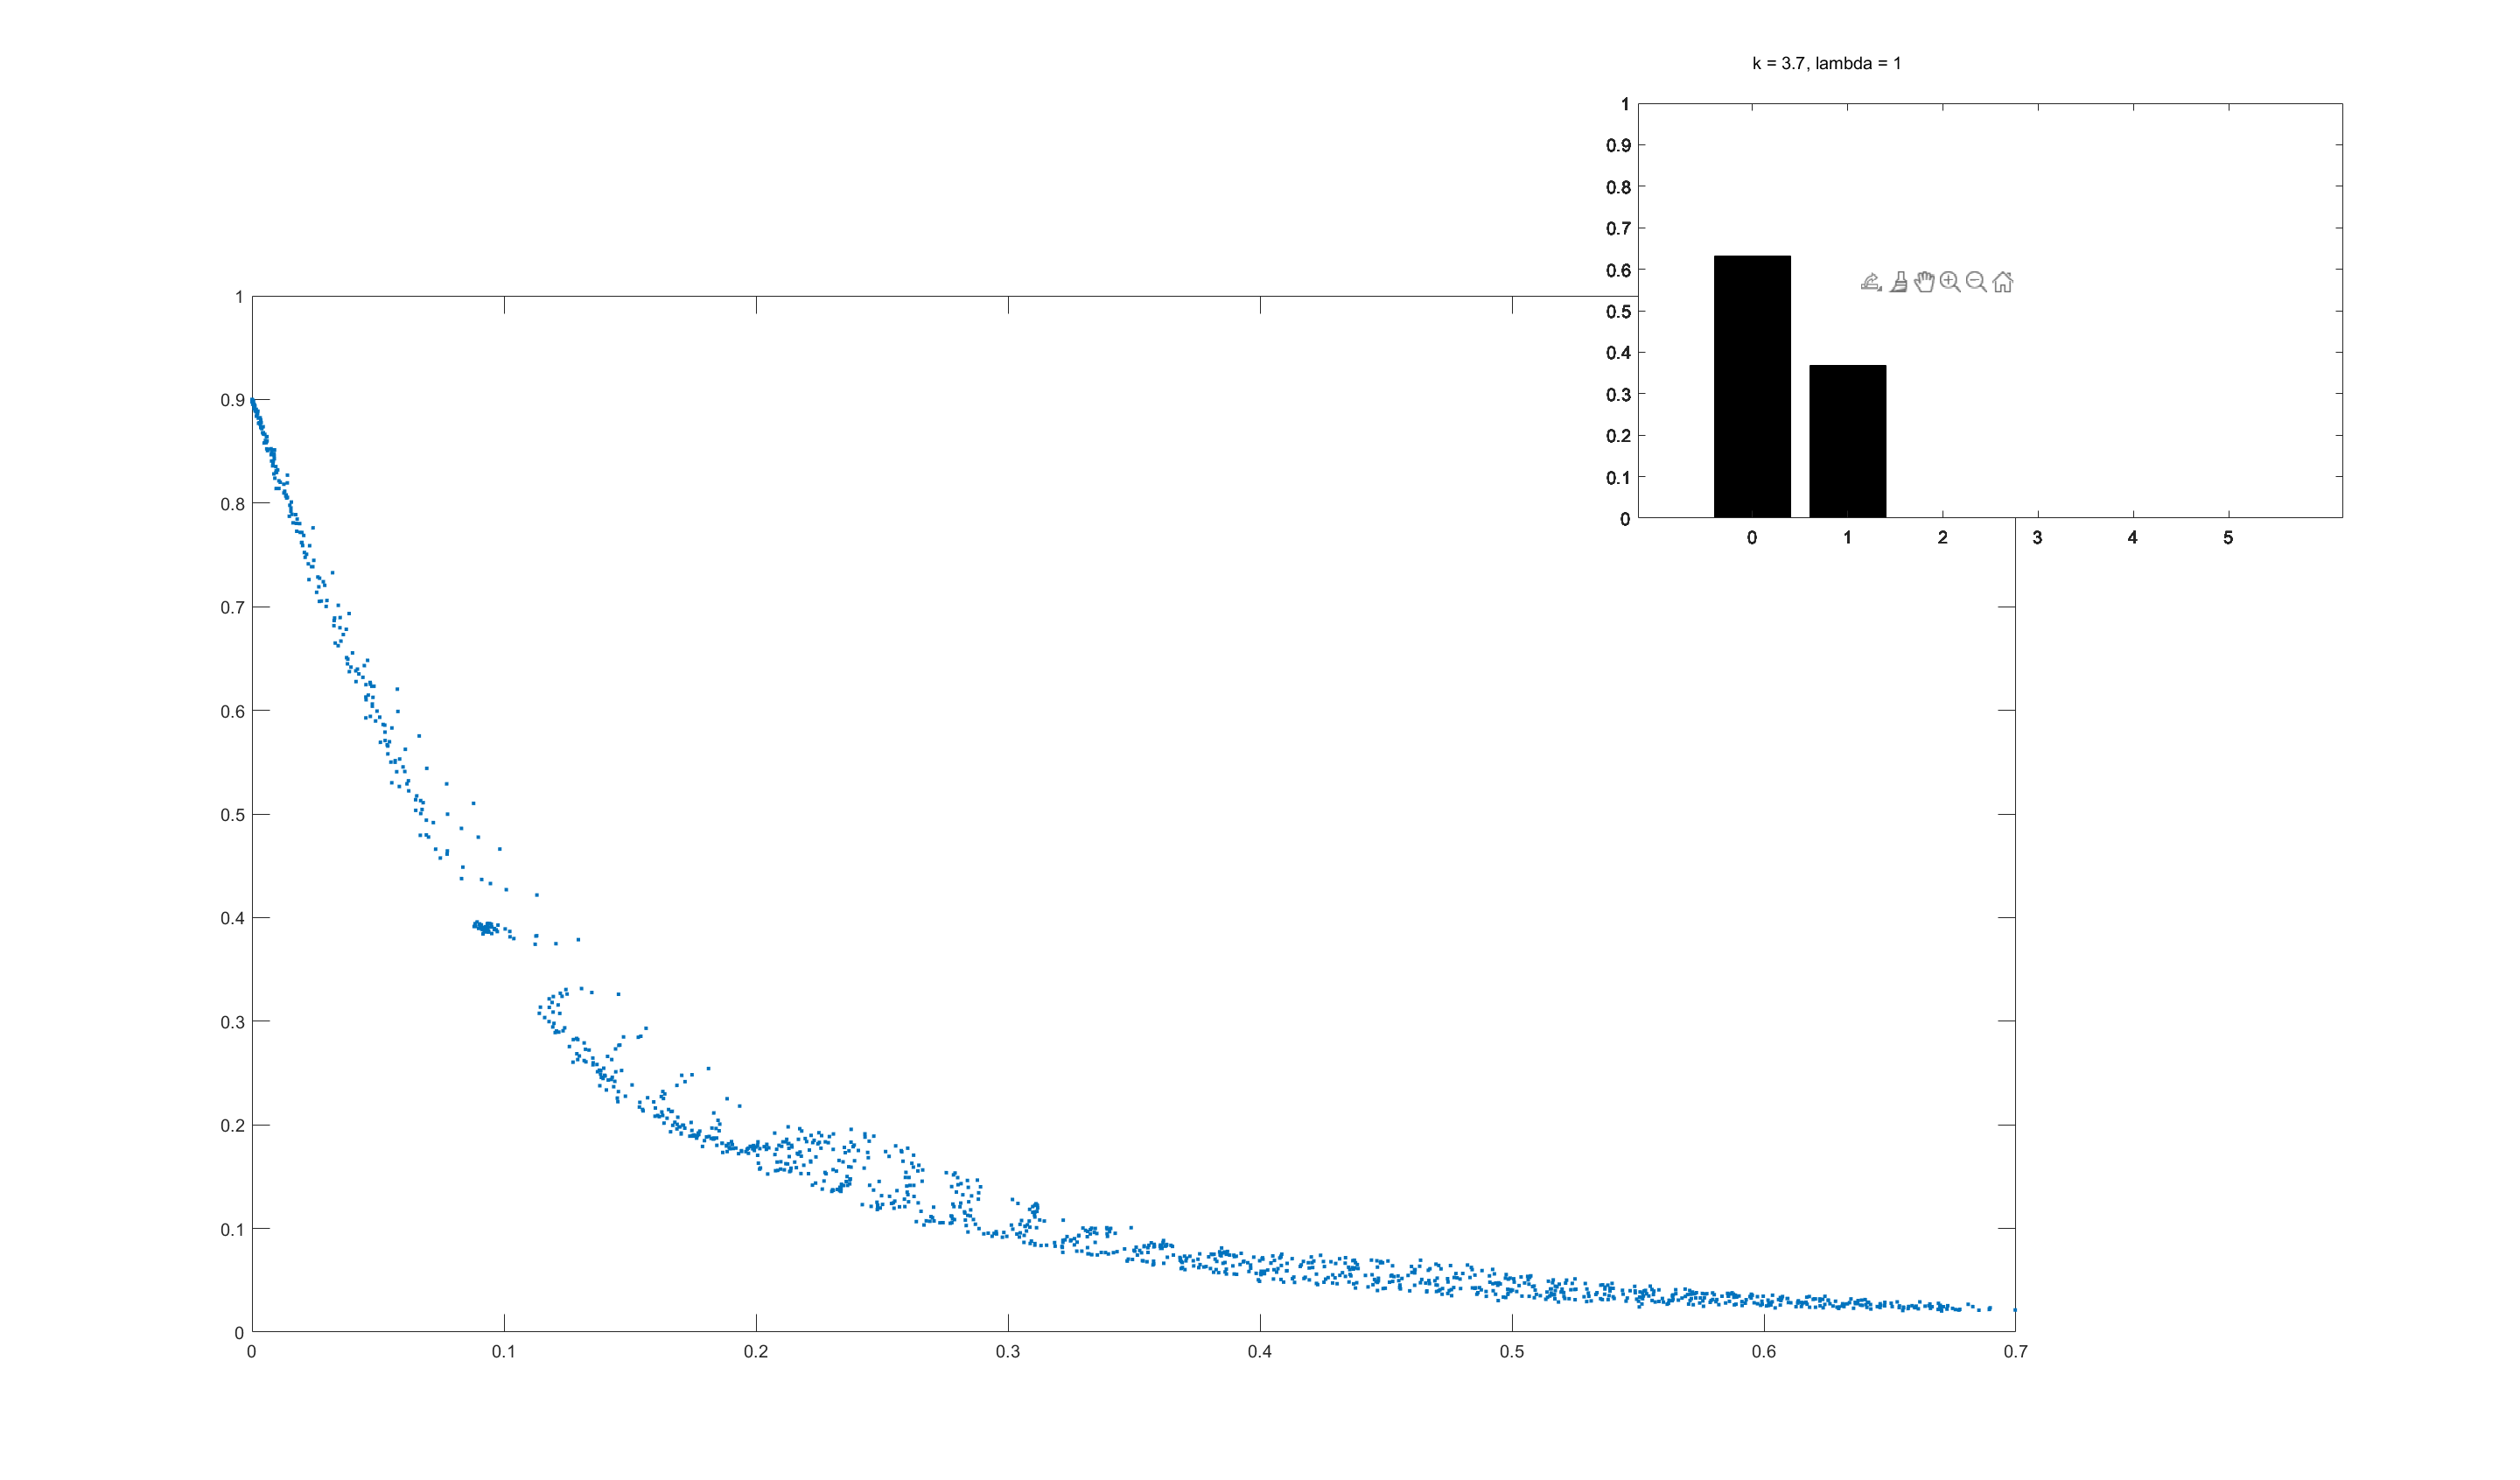

f = figure;
ax1 = axes('Position',[0.1 0.1 0.7 0.7]);
xlabel(ax1,'Mortality Cost')
ylabel(ax1,'Kin Competition Cost')
plot(out_mortcost,out_kincost,'.')
htext = text(0,1.1,'Click a point');
for rep=1:30
g = ginput(1);
delete(htext)
ax2 = axes('Position',[0.65 0.65 0.28 0.28]);
cla
D = pdist2(mk,g);
[~,ix] = min(D);
pt=mk(ix,:);
bar(0:5,kernels(ix,:),'k')
param = params(ix,:);
htext = text(0,1.1,strcat(['k = ', num2str(param(1)), ', lambda = ', num2str(param(2))]));
ylim([0 1])
end